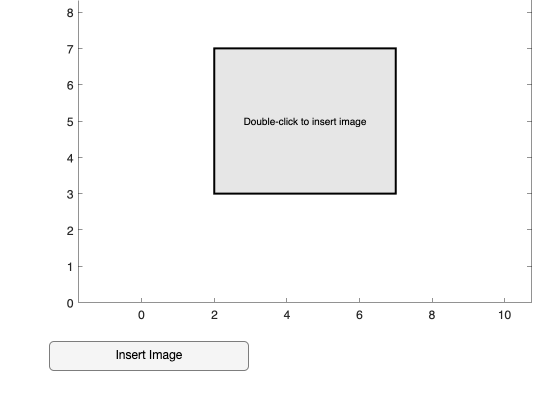

%% Image in Rectangle
% This Live Script creates a rectangular area where you can insert an image.

%% Initialize Figure
fig = uifigure('Name', 'Image in Rectangle', 'Color', 'white');
ax = uiaxes(fig, ...
    'Position', [50 100 500 400], ...
    'XLim', [0 10], ...
    'YLim', [0 10], ...
    'Box', 'on', ...
    'GridLineStyle', '-');
title(ax, 'Click the rectangle to insert an image');
axis(ax, 'equal');

%% Create Rectangle
rect_pos = [2, 3, 5, 4];  % [x, y, width, height]
rectangle(ax, 'Position', rect_pos, ...
    'FaceColor', [0.9 0.9 0.9], ...
    'EdgeColor', 'k', ...
    'LineWidth', 2);

%% Add Instructions
text(ax, rect_pos(1) + rect_pos(3)/2, rect_pos(2) + rect_pos(4)/2, ...
    'Double-click to insert image', ...
    'HorizontalAlignment', 'center', ...
    'FontSize', 10);

%% Add Interactive Button
btn = uibutton(fig, ...
    'Position', [50 50 200 30], ...
    'Text', 'Insert Image', ...
    'ButtonPushedFcn', @(btn,event) insertImage(ax, rect_pos));


%% Image Insertion Function
function insertImage(ax, rect_pos)
    % Open file dialog
    [filename, pathname] = uigetfile(...
        {'*.jpg;*.jpeg;*.png;*.bmp;*.tif;*.tiff', ...
        'Image Files (*.jpg, *.png, *.bmp, *.tif)'}, ...
        'Select an Image');
    
    if isequal(filename, 0)
        return;  % User cancelled
    end
    
    try
        % Read and display image
        img = imread(fullfile(pathname, filename));
        
        % Clear previous image
        h_img = findobj(ax, 'Type', 'image');
        if ~isempty(h_img)
            delete(h_img);
        end
        
        % Display new image
        image(ax, 'XData', [rect_pos(1), rect_pos(1)+rect_pos(3)], ...
                 'YData', [rect_pos(2)+rect_pos(4), rect_pos(2)], ...
                 'CData', img);
        
        % Make rectangle transparent
        h_rect = findobj(ax, 'Type', 'rectangle');
        set(h_rect, 'FaceColor', 'none');
        
        % Update title
        title(ax, ['Image: ' filename]);
        
    catch ME
        errordlg(['Error loading image: ' ME.message], 'Image Error');
    end
end